%% initialize environments
clc;
clear variables;

%% set AudioFileManipulator class parameters
input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word 1.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.normalize();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word 1.wav
output_file_path : default.wav
signal shape : (189282, 1)
sample_rate: 48000 [Hz]
             Filename: 'D:\名城大学\研究室\研究\データセット\4モーラ単語リスト セット 1\4モーラ単語リスト noMask\set1_noMask_word 1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 189282
             Duration: 3.9434
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 24

--------------------------------------------



%% set label file path and load label
label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト noMask/set1_noMask_word 1_label.txt";
label = sploadlabel(label_file_path, 'sec');

figure('Position', [0 0 800 450]);
plot((1 : length(audio_file_manipulator.signal)) / audio_file_manipulator.sample_rate, audio_file_manipulator.signal);
spplotlabel(label, 'r:');
font_size = 14;
xlim([1.7 2.5]);
title("set1 no mask word " + int2str(file_index) + "signal with label", "FontSize", font_size);
xlabel("Time [s]", "FontSize", font_size);
output_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト noMask LabeledSignal/set1_noMask_word 1.png";
saveas(gcf, output_file_path);
delete(gcf);

wide_framem = 3.33;
framem = wide_framem;
shiftm = framem / 4;
frame_length = round(framem * audio_file_manipulator.sample_rate / 1000);
hop_length = round(shiftm * audio_file_manipulator.sample_rate / 1000);
fft_point = max(2 .^ nextpow2(frame_length), 256);

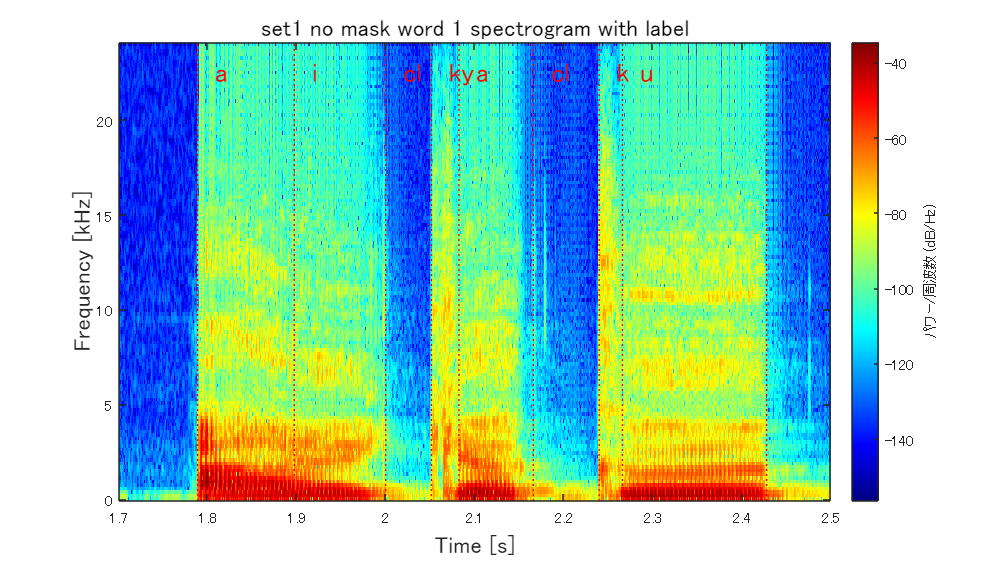

figure('Position', [0 0 800 450]);
spectrogram(audio_file_manipulator.signal, hamming(frame_length), frame_length - hop_length, fft_point, audio_file_manipulator.sample_rate, 'yaxis');
colormap jet;
spplotlabel(label, 'r:');
xlim([1.7 2.5]);
title("set1 no mask word 1 spectrogram with label", "FontSize", font_size);
xlabel("Time [s]", "FontSize", font_size);
ylabel("Frequency [kHz]", "FontSize", font_size);
output_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト noMask LabeledSpectrogram/set1_noMask_word 1.png";
saveas(gcf, output_file_path);

delete(gcf);

%% set AudioFileManipulator class parameters
input_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word 1.wav";

%% generate AudioFileManipulator instance and confirm properties
audio_file_manipulator = AudioFileManipulator(input_file_path);
audio_file_manipulator.load_properties();
audio_file_manipulator.normalize();
audio_file_manipulator.display_properties();

--------------------------------------------
---------- Audio File Manipulator ----------
input_file_path : D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word 1.wav
output_file_path : default.wav
signal shape : (194558, 1)
sample_rate: 48000 [Hz]
             Filename: 'D:\名城大学\研究室\研究\データセット\4モーラ単語リスト セット 1\4モーラ単語リスト withMask\set1_withMask_word 1.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 48000
         TotalSamples: 194558
             Duration: 4.0533
                Title: []
              Comment: []
               Artist: []
        BitsPerSample: 24

--------------------------------------------



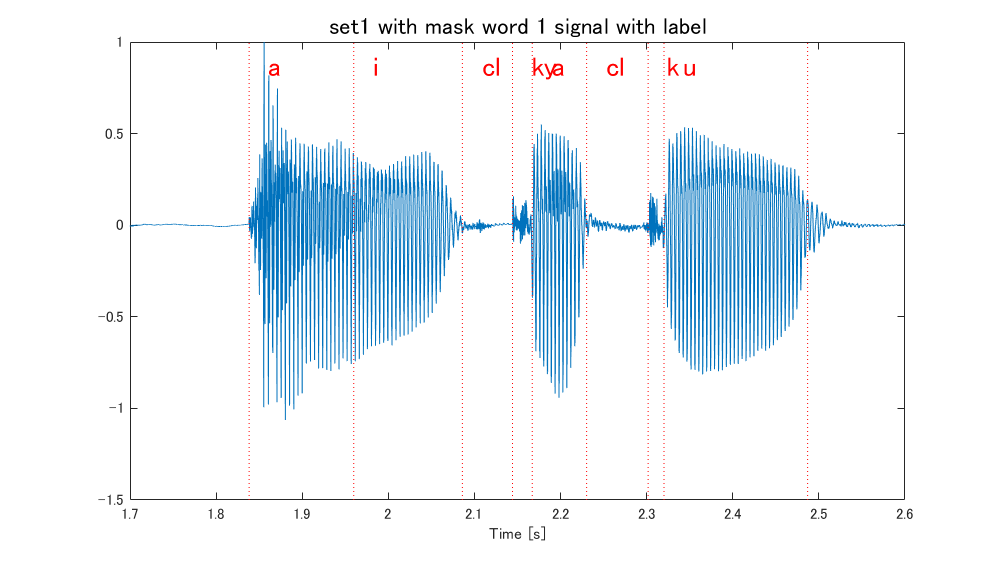

%% set label file path and load label
label_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト セット 1/4モーラ単語リスト withMask/set1_withMask_word 1_label.txt";
figure('Position', [0 0 800 450]);
label = sploadlabel(label_file_path, 'sec');
plot((1 : length(audio_file_manipulator.signal)) / audio_file_manipulator.sample_rate, audio_file_manipulator.signal);
spplotlabel(label, 'r:');
xlim([1.7 2.6]);
title("set1 with mask word 1 signal with label", "FontSize", font_size);
xlabel("Time [s]");
output_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト withMask LabeledSignal/set1_withMask_word 1.png";
saveas(gcf, output_file_path);

delete(gcf);

wide_framem = 3.33;
framem = wide_framem;
shiftm = framem / 4;
frame_length = round(framem * audio_file_manipulator.sample_rate / 1000);
hop_length = round(shiftm * audio_file_manipulator.sample_rate / 1000);
fft_point = max(2 .^ nextpow2(frame_length), 256);

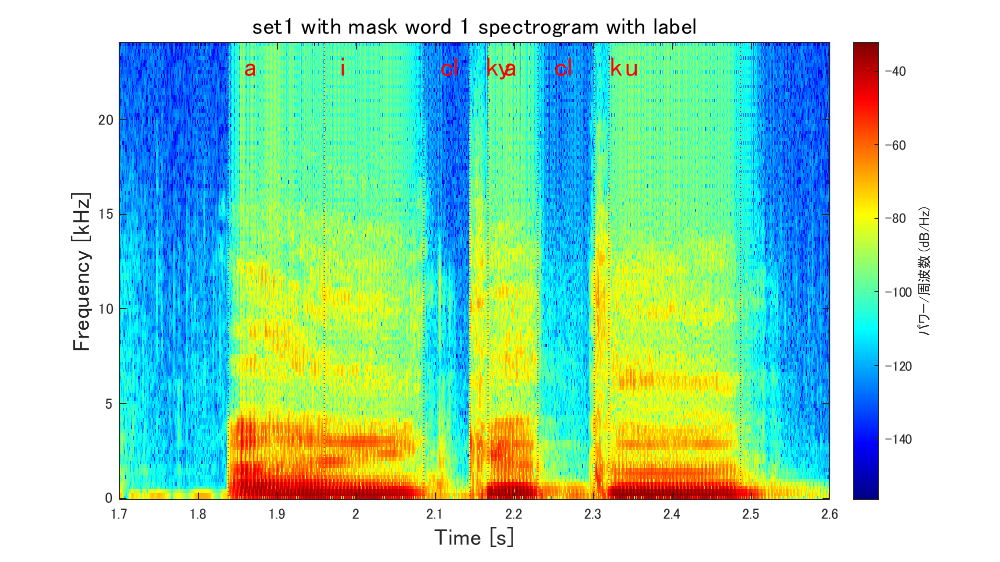

figure('Position', [0 0 800 450]);
spectrogram(audio_file_manipulator.signal, hamming(frame_length), frame_length - hop_length, fft_point, audio_file_manipulator.sample_rate, 'yaxis');
colormap jet;
spplotlabel(label, 'r:');
xlim([1.7 2.6]);
title("set1 with mask word 1 spectrogram with label", "FontSize", font_size);
xlabel("Time [s]", "FontSize", font_size);
ylabel("Frequency [kHz]", "FontSize", font_size);
output_file_path = "D:/名城大学/研究室/研究/データセット/4モーラ単語リスト プロット 1/4モーラ単語リスト withMask LabeledSpectrogram/set1_withMask_word 1.png";
saveas(gcf, output_file_path);

delete(gcf);